# ECE 2409

#### Fall 2020

#### Theo Andonyadis

#### Homework 5

This preliminary bit creates a plot of the two stocks based on days, ford in red.

clc;clear;close all
c=datetime;
fprintf('Last run was %s\n',c)

Last run was 03-Feb-2021 20:16:38


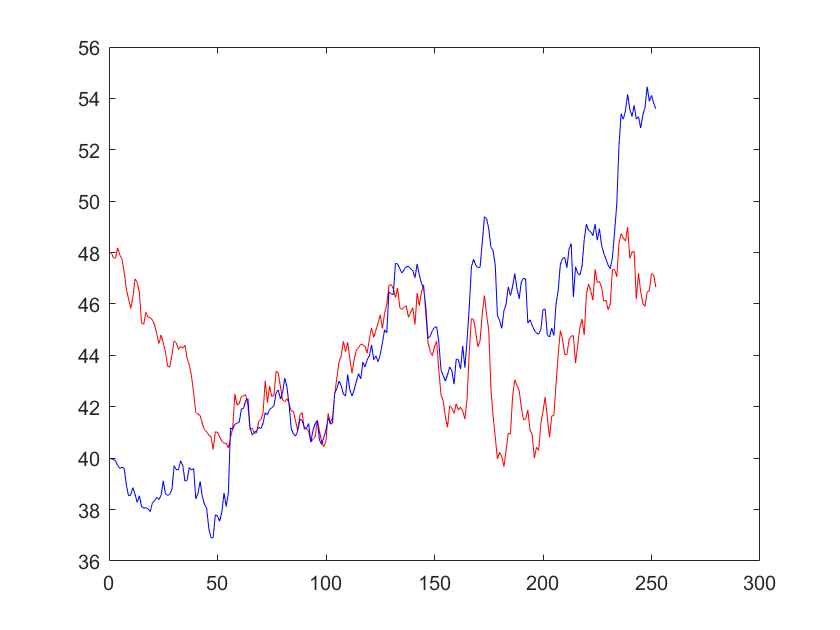

load fordstock
load gmstock
plot(ford,"Color","R")
hold on
plot(gm,"Color","B")

Question 1 - This code creates a logical array based on the gm stock, where 1's are days when the stock closed above $45 or below $40, and all other days are zeros. It stores the amount of these days in variable a1, then prints.

gmp1=(gm>45 | gm<40);
a1=sum(gmp1);
fprintf("There were %i days where the GM stock closed above $45 or below $40",a1)

There were 155 days where the GM stock closed above $45 or below $40

Question 2 - This code creates a logical array based on the gm stock, where 1's are days when the stock closed at or between $40 and $45, and all other days are zeros. It stores the amount of these days in variable a2, then prints.

gmp2=(gm<=45 & gm>=40);
gmp2

gmp2 = 252×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


a2=sum(gmp2);
fprintf("There were %i days where the GM stock closed between $40 and $45, inclusive",a2)

There were 97 days where the GM stock closed between $40 and $45, inclusive

Question 3 - This code creates a logical array where 1's are days when ford stock closed at a higher price than gm. It stores the amount of these days in variable a3, then prints.

ford;
gm;
fordogm=(ford>gm);
a3=sum(fordogm);
fprintf("There were %i days where the Ford stock closed higher than GM",a3)

There were 114 days where the Ford stock closed higher than GM

Question 4 - This code creates a logical array where 1's are days when gm stock closed at a higher price than ford. It then finds the location of the first 1 in this array, the first day which gm stock closed higher than ford, then prints.

gmoford=(ford<gm);
a4=find(gmoford,1,'first');
find(gmoford)

ans =     56
    64
    65
    67
    68
    80
    81
    82
    90
    91


fprintf("The Ford stock fell below GM for the first time on day %i",a4)

The Ford stock fell below GM for the first time on day 56

Question 5 - This code finds the location of the last 1 in the array from question 3, determining the day when gm stock closed higher than ford and never fell back below, then prints.

a5=find(fordogm,1,'last');
fprintf("The GM stock closed higher than Ford and never fell back on day %i",a5)

The GM stock closed higher than Ford and never fell back on day 145